**Ionic Current Model of Bipolar Cells**

Set constants

% Timespan. sec.
tspan = [0, 5];

% Hyperpolarizing current injections. pA.
hyper_injections = [-30, -20, -10];
num_hyper = length(hyper_injections);

% Depolarizing current injections. pA.
depolar_injections = [30, 20, 10];
num_de = length(depolar_injections);

*Compute voltage (hyperpolarizing)*

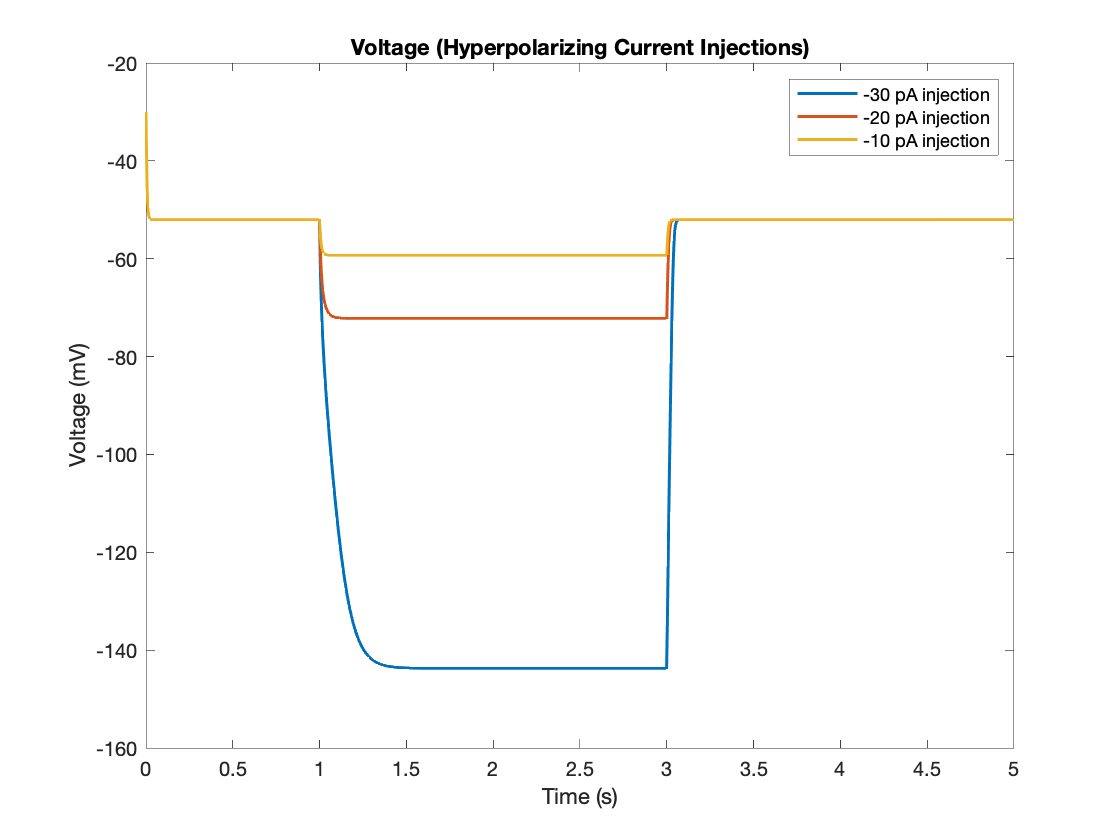

% Compute voltages.
[t_30, res_30] = calcV(tspan,hyper_injections(1));
V_30 = res_30(:,5);
[t_20, res_20] = calcV(tspan,hyper_injections(2));
V_20 = res_20(:,5);
[t_10, res_10] = calcV(tspan,hyper_injections(3));
V_10 = res_10(:,5);

% Interpolation to account for different sizes.
maxLen = max([length(t_30), length(t_20), length(t_10)]);
new_T = linspace(tspan(1), tspan(2), maxLen);
newV_30 = interp1(t_30, V_30, new_T);
newV_20 = interp1(t_20, V_20, new_T);
newV_10 = interp1(t_10, V_10, new_T);

% Plot the results.
plot(new_T, newV_30, new_T, newV_20, new_T, newV_10, 'LineWidth', 1.5)
ylim([-160 -20])
title('Voltage (Hyperpolarizing Current Injections)')
xlabel('Time (s)')
ylabel('Voltage (mV)')
legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Compute voltage (depolarizing)*

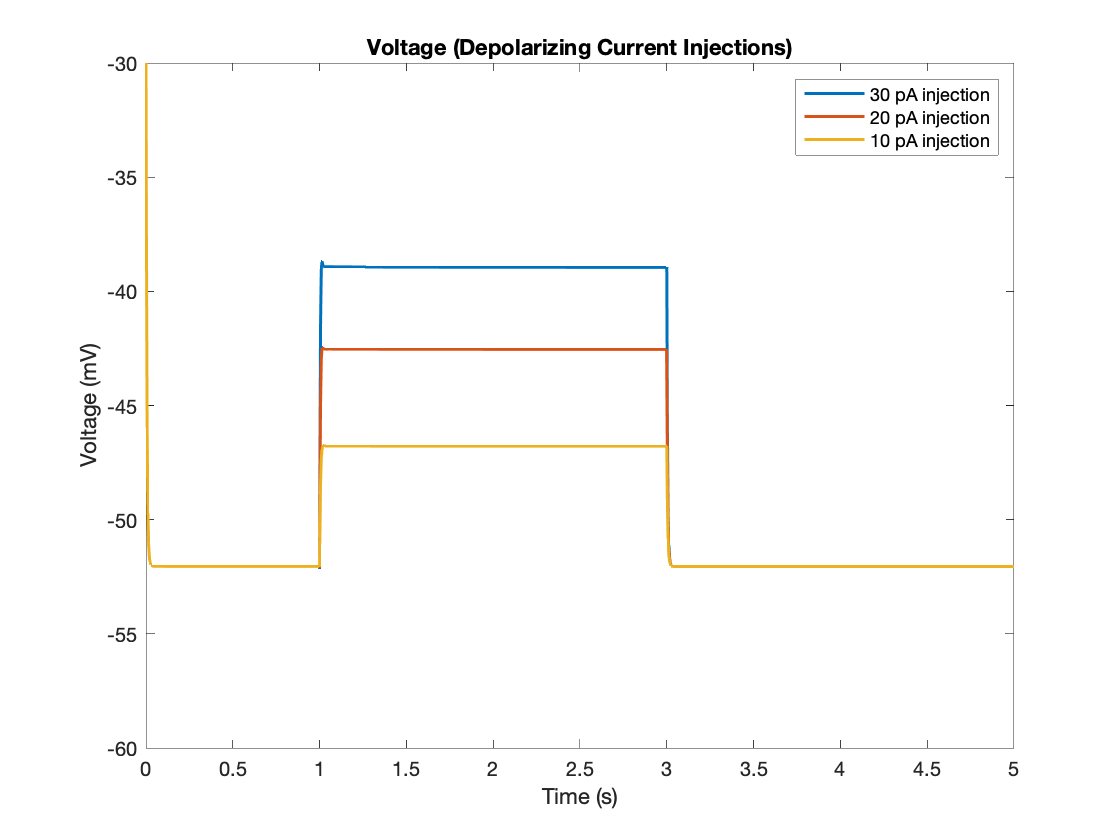

% Compute voltages.
[t30, res30] = calcV(tspan,depolar_injections(1));
V30 = res30(:,5);
[t20, res20] = calcV(tspan,depolar_injections(2));
V20 = res20(:,5);
[t10, res10] = calcV(tspan,depolar_injections(3));
V10 = res10(:,5);

% Interpolation to account for different sizes.
maxLen = max([length(t30), length(t20), length(t10)]);
newT = linspace(tspan(1), tspan(2), maxLen);
newV30 = interp1(t30, V30, newT);
newV20 = interp1(t20, V20, newT);
newV10 = interp1(t10, V10, newT);

% Plot the results.
plot(newT, newV30, newT, newV20, newT, newV10, 'LineWidth', 1.5)
ylim([-60 -30])
title('Voltage (Depolarizing Current Injections)')
xlabel('Time (s)')
ylabel('Voltage (mV)')
legend('30 pA injection','20 pA injection', '10 pA injection')

*Calcium current (hyperpolarizing)*

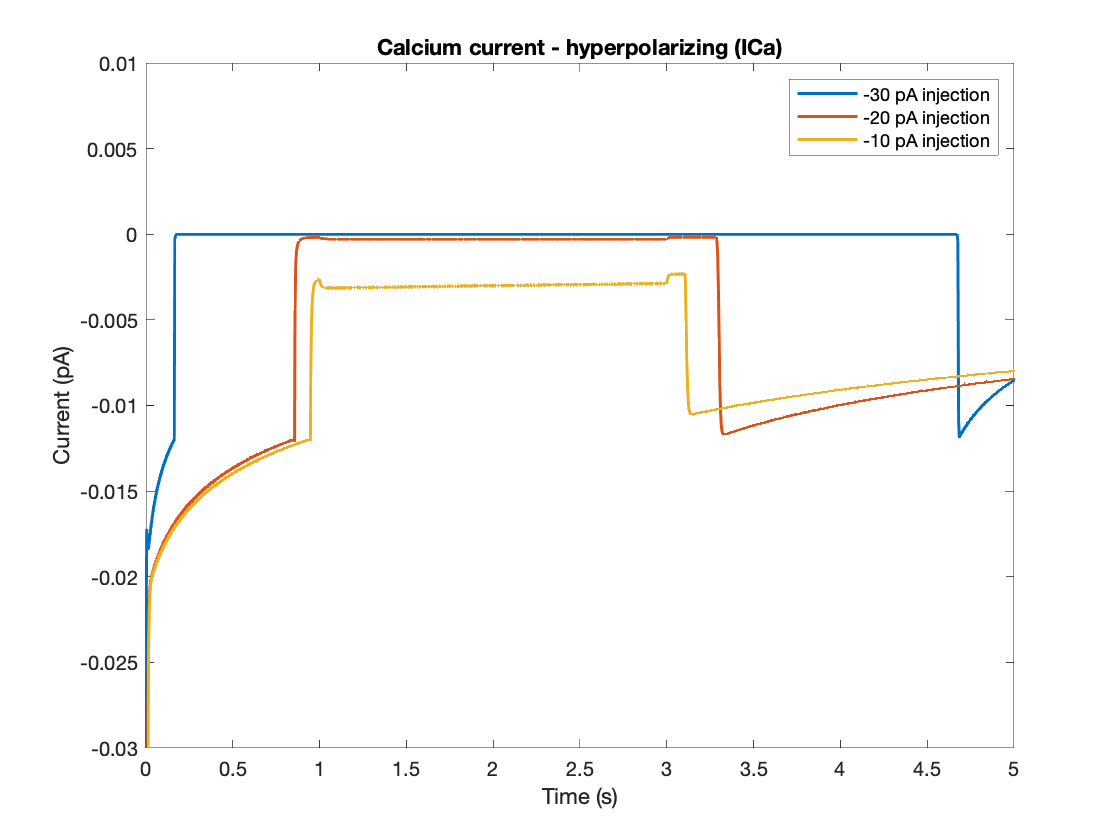

% Compute currents.
mCa_30 = doFit(new_T, res_30(:,3));
Cas_30 = doFit(new_T, res_30(:,11));
ICa_30 = calcICa(new_T, mCa_30, Cas_30, newV_30);
mCa_20 = doFit(new_T, res_20(:,3));
Cas_20 = doFit(new_T, res_20(:,11));
ICa_20 = calcICa(new_T, mCa_20, Cas_20, newV_20);
mCa_10 = doFit(new_T, res_10(:,3));
Cas_10 = doFit(new_T, res_10(:,11));
ICa_10 = calcICa(new_T, mCa_10, Cas_10, newV_10);

% Plot the results.
plot(new_T, ICa_30, new_T, ICa_20, new_T, ICa_10, 'LineWidth', 1.5)
ylim([-0.03 0.01])
title('Calcium current - hyperpolarizing (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')
legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Calcium current (depolarizing)*

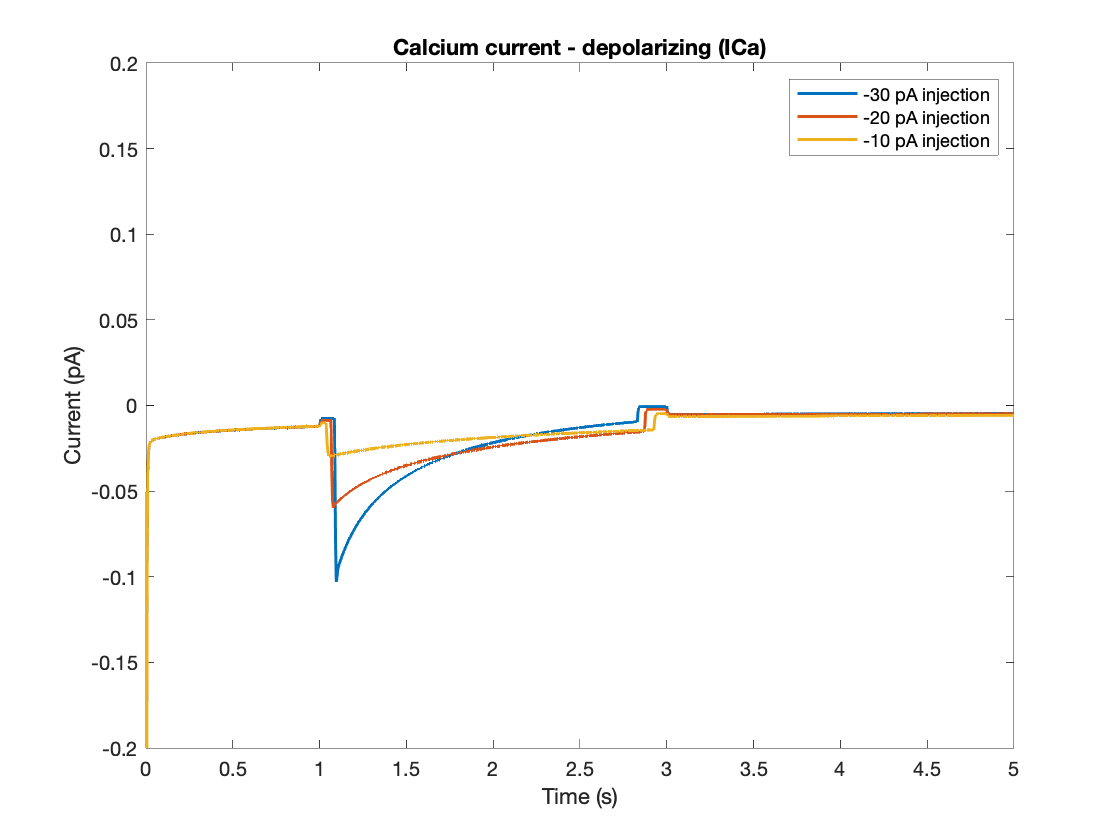

% Compute currents.
mCa30 = doFit(newT, res30(:,3));
Cas30 = doFit(newT, res30(:,11));
ICa30 = calcICa(newT, mCa30, Cas30, newV30);
mCa20 = doFit(newT, res20(:,3));
Cas20 = doFit(newT, res20(:,11));
ICa20 = calcICa(newT, mCa20, Cas20, newV20);
mCa10 = doFit(newT, res10(:,3));
Cas10 = doFit(newT, res10(:,11));
ICa10 = calcICa(newT, mCa10, Cas10, newV10);

% Plot the results.
plot(newT, ICa30, newT, ICa20, newT, ICa10, 'LineWidth', 1.5)
ylim([-0.2 0.2])
title('Calcium current - depolarizing (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')
legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Calcium-dependent K current (hyperpolarizing)*

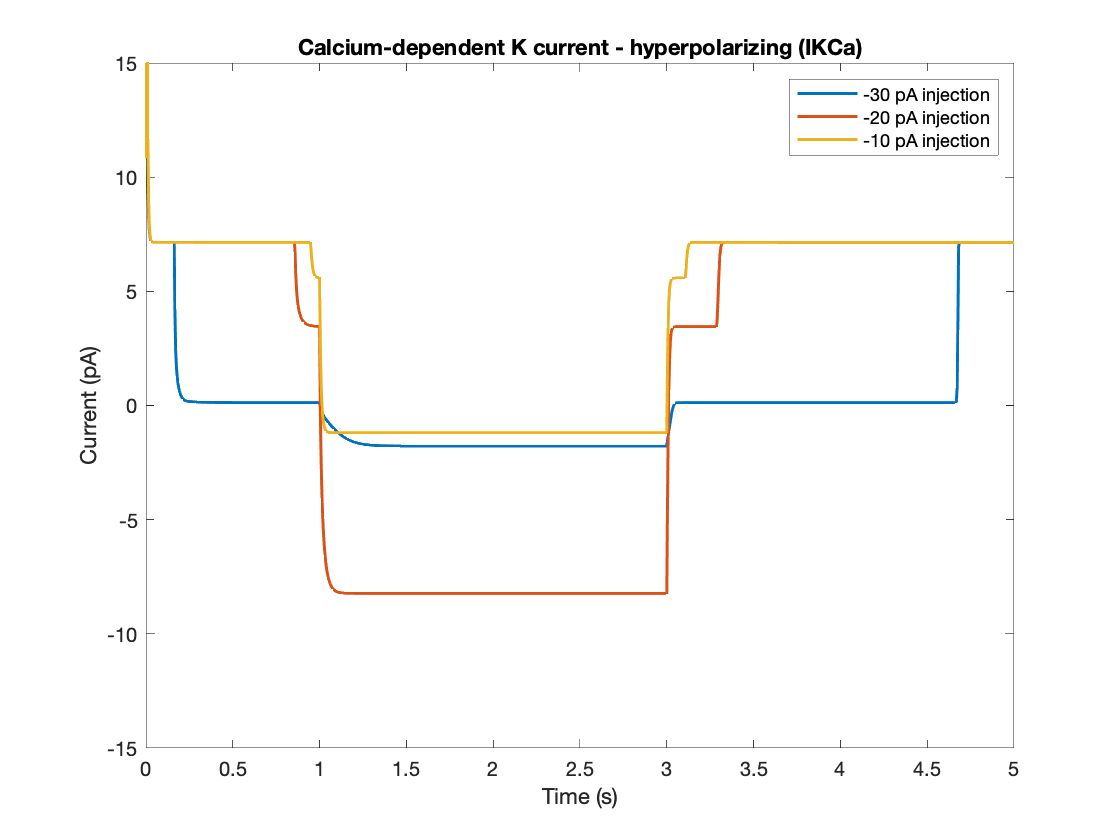

% Compute currents.
mKc_30 = doFit(new_T, res_30(:,4));
Cas_30 = doFit(new_T, res_30(:,11));
IKCa_30 = calcIKCa(new_T, mKc_30, Cas_30, newV_30);
mKc_20 = doFit(new_T, res_20(:,4));
Cas_20 = doFit(new_T, res_20(:,11));
IKCa_20 = calcIKCa(new_T, mKc_20, Cas_20, newV_20);
mKc_10 = doFit(new_T, res_10(:,4));
Cas_10 = doFit(new_T, res_10(:,11));
IKCa_10 = calcIKCa(new_T, mKc_10, Cas_10, newV_10);

% Plot the results.
plot(new_T, IKCa_30, new_T, IKCa_20, new_T, IKCa_10, 'LineWidth', 1.5)
ylim([-15 15])
title('Calcium-dependent K current - hyperpolarizing (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')
legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Calcium-dependent K current (depolarizing)*

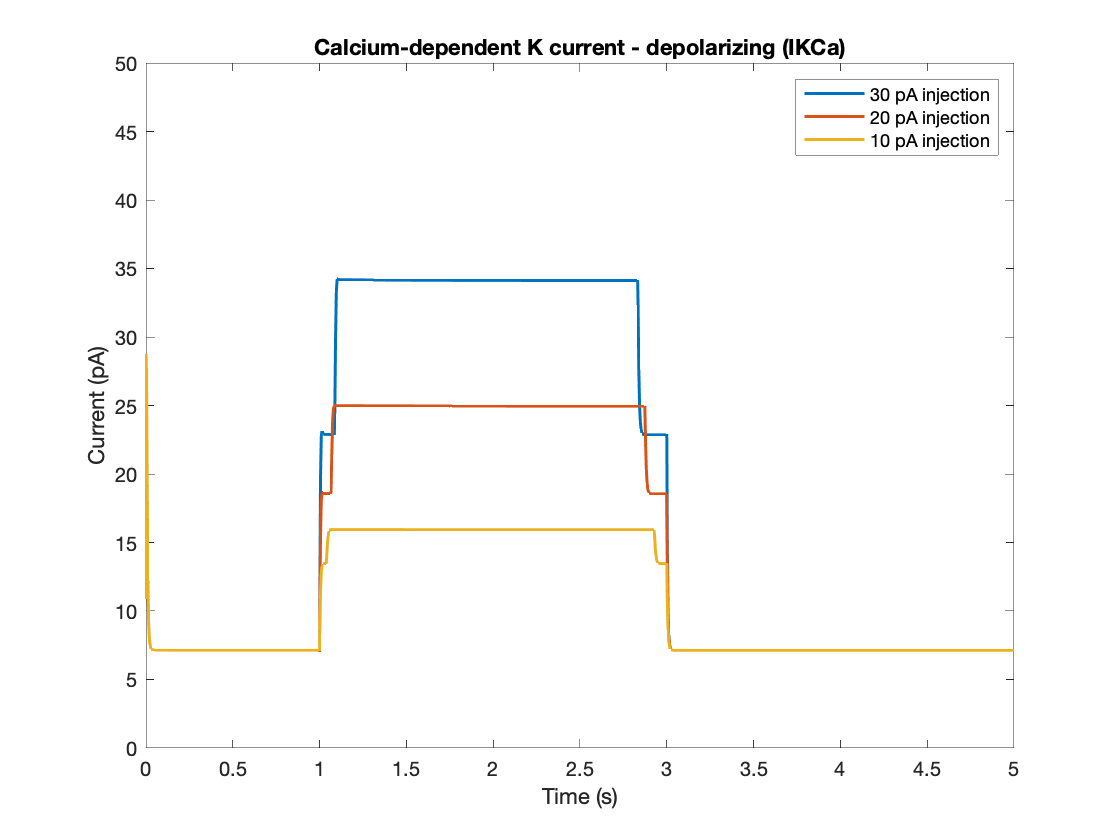

% Compute currents.
mKc30 = doFit(newT, res30(:,4));
Cas30 = doFit(newT, res30(:,11));
IKCa30 = calcIKCa(newT, mKc30, Cas30, newV30);
mKc20 = doFit(newT, res20(:,4));
Cas20 = doFit(newT, res20(:,11));
IKCa20 = calcIKCa(newT, mKc20, Cas20, newV20);
mKc10 = doFit(newT, res10(:,4));
Cas10 = doFit(newT, res10(:,11));
IKCa10 = calcIKCa(newT, mKc10, Cas10, newV10);

% Plot the results.
plot(newT, IKCa30, newT, IKCa20, newT, IKCa10, 'LineWidth', 1.5)
ylim([0 50])
title('Calcium-dependent K current - depolarizing (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')
legend('30 pA injection','20 pA injection','10 pA injection')

*Delayed rectifying potassium current (hyperpolarizing)*

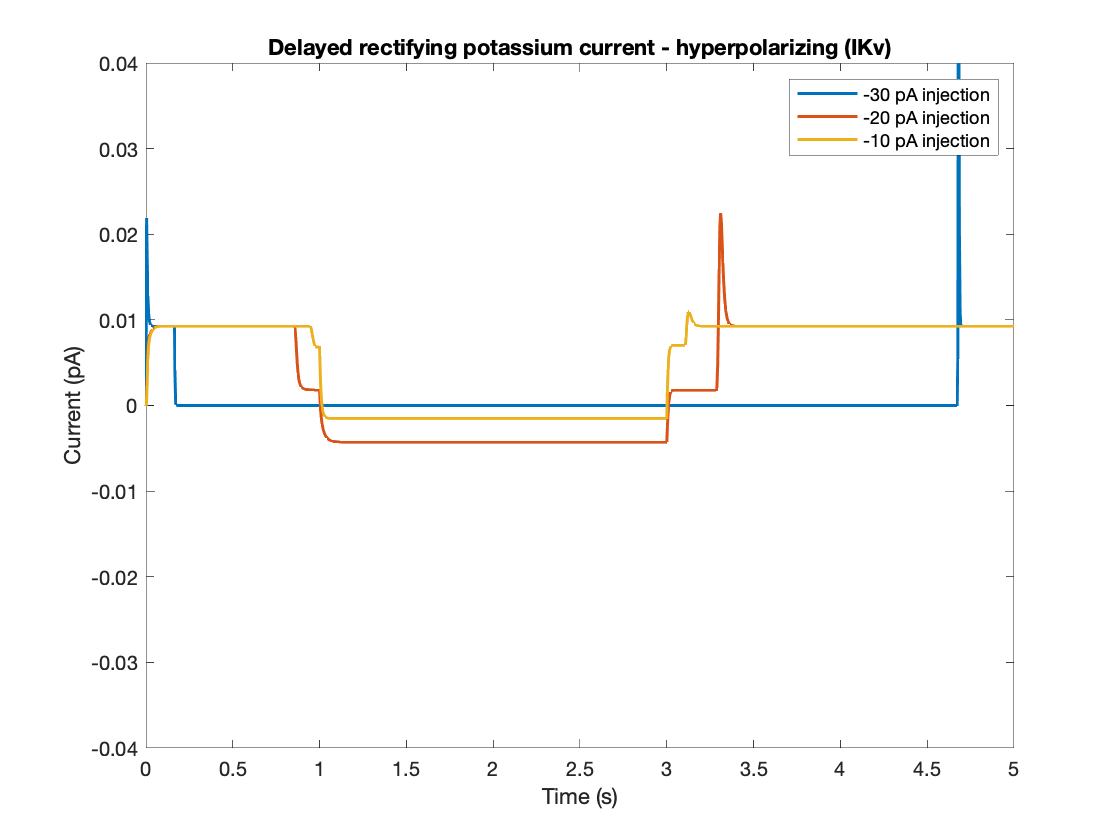

% Compute currents.
mKv_30 = doFit(new_T, res_30(:,1));
hKv_30 = doFit(new_T, res_30(:,2));
IKv_30 = calcIKv(new_T, mKv_30, hKv_30, newV_30);
mKv_20 = doFit(new_T, res_20(:,1));
hKv_20 = doFit(new_T, res_20(:,2));
IKv_20 = calcIKv(new_T, mKv_20, hKv_20, newV_20);
mKv_10 = doFit(new_T, res_10(:,1));
hKv_10 = doFit(new_T, res_10(:,2));
IKv_10 = calcIKv(new_T, mKv_10, hKv_10, newV_10);

% Plot the results.
plot(new_T, IKv_30, new_T, IKv_20, new_T, IKv_10, 'LineWidth', 1.5)
ylim([-0.04 0.04])
title('Delayed rectifying potassium current - hyperpolarizing (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')
legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Delayed rectifying potassium current (depolarizing)*

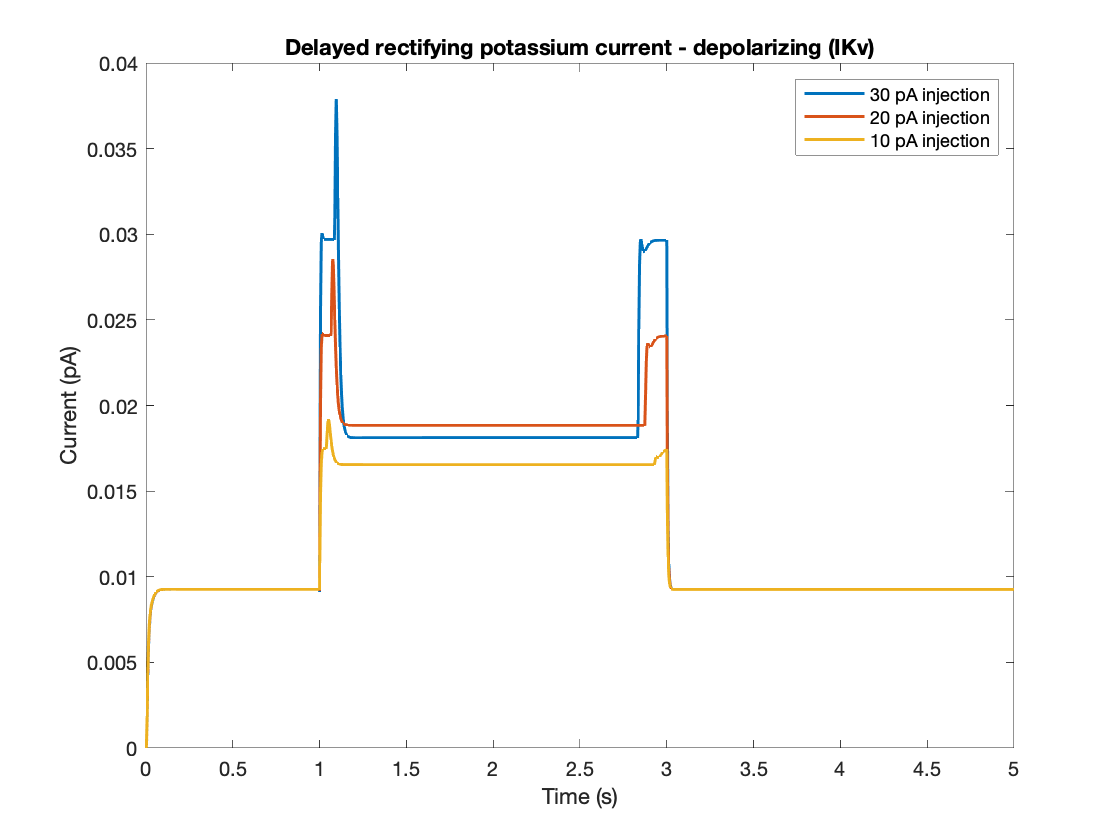

% Compute currents.
mKv30 = doFit(newT, res30(:,1));
hKv30 = doFit(newT, res30(:,2));
IKv30 = calcIKv(newT, mKv30, hKv30, newV30);
mKv20 = doFit(newT, res20(:,1));
hKv20 = doFit(newT, res20(:,2));
IKv20 = calcIKv(newT, mKv20, hKv20, newV20);
mKv10 = doFit(newT, res10(:,1));
hKv10 = doFit(newT, res10(:,2));
IKv10 = calcIKv(newT, mKv10, hKv10, newV10);

% Plot the results.
plot(newT, IKv30, newT, IKv20, newT, IKv10, 'LineWidth', 1.5)
ylim([0 0.04])
title('Delayed rectifying potassium current - depolarizing (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')
legend('30 pA injection','20 pA injection','10 pA injection')

*Hyperpolarization activated current (hyperpolarizing)*

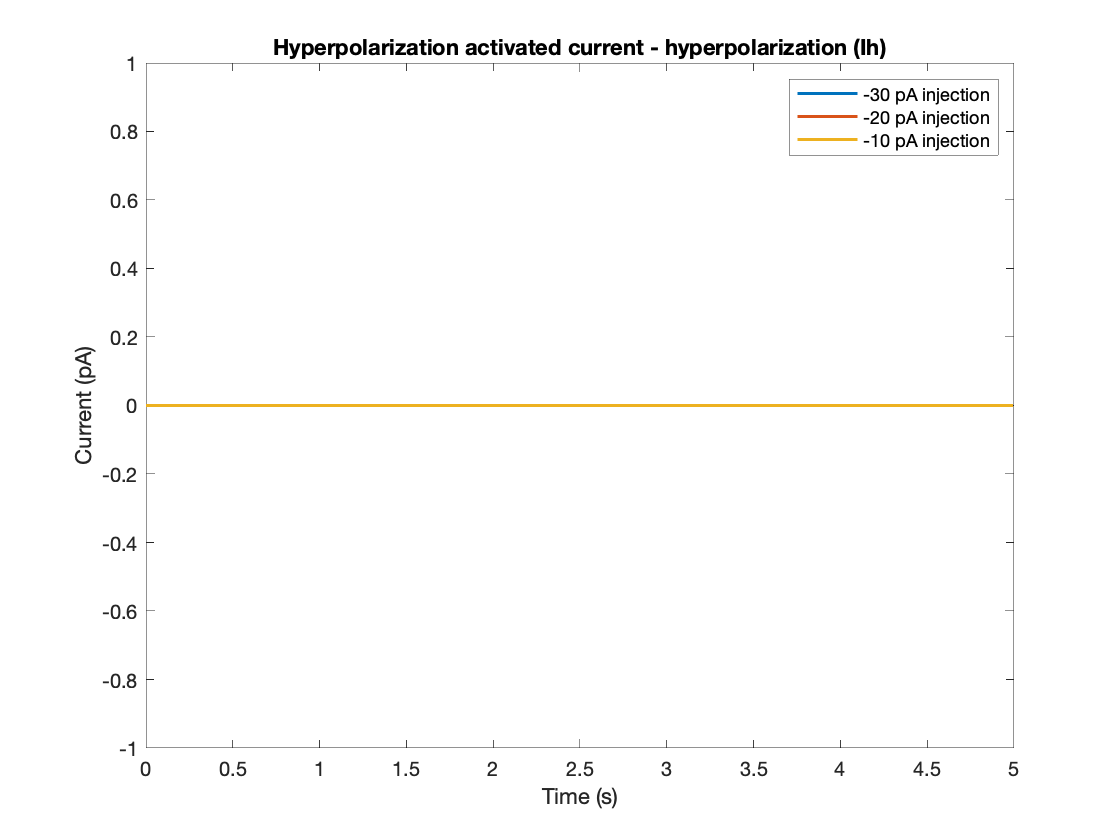

% Compute currents.
O1_30 = doFit(new_T, res_30(:,8));
O2_30 = doFit(new_T, res_30(:,9));
O3_30 = doFit(new_T, res_30(:,10));
Ih_30 = calcIh(new_T, O1_30, O2_30, O3_30, newV_30);
O1_20 = doFit(new_T, res_20(:,8));
O2_20 = doFit(new_T, res_20(:,9));
O3_20 = doFit(new_T, res_20(:,10));
Ih_20 = calcIh(new_T, O1_20, O2_20, O3_20, newV_20);
O1_10 = doFit(new_T, res_10(:,8));
O2_10 = doFit(new_T, res_10(:,9));
O3_10 = doFit(new_T, res_10(:,10));
Ih_10 = calcIh(new_T, O1_10, O2_10, O3_10, newV_10);

% Plot the results.
plot(new_T, Ih_30, new_T, Ih_20, new_T, Ih_10, 'LineWidth', 1.5)
ylim([-1 1])
title('Hyperpolarization activated current - hyperpolarization (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')
legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Hyperpolarization activated current (depolarizing)*

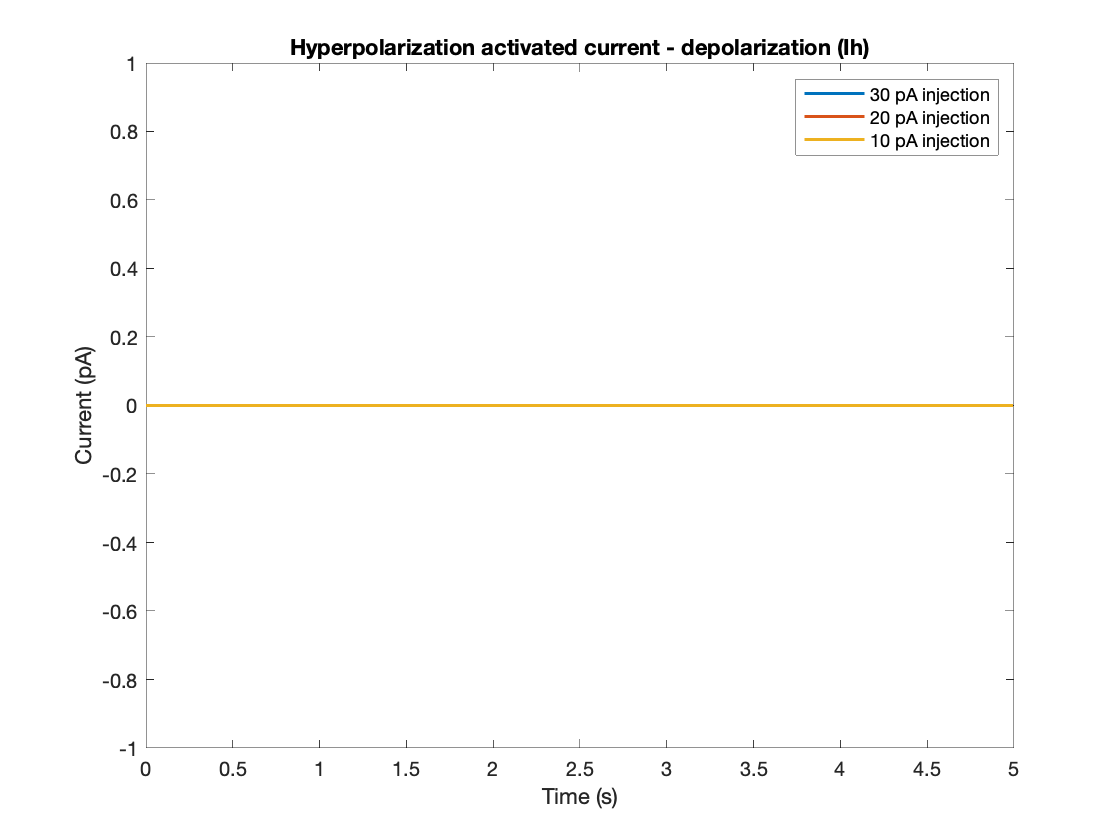

% Compute currents.
O130 = doFit(newT, res30(:,8));
O230 = doFit(newT, res30(:,9));
O330 = doFit(newT, res30(:,10));
Ih30 = calcIh(newT, O130, O230, O330, newV30);
O120 = doFit(newT, res20(:,8));
O220 = doFit(newT, res20(:,9));
O320 = doFit(newT, res20(:,10));
Ih20 = calcIh(newT, O120, O220, O320, newV20);
O110 = doFit(newT, res10(:,8));
O210 = doFit(newT, res10(:,9));
O310 = doFit(newT, res10(:,10));
Ih10 = calcIh(newT, O110, O210, O310, newV10);

% Plot the results.
plot(newT, Ih30, newT, Ih20, newT, Ih10, 'LineWidth', 1.5)
ylim([-1 1])
title('Hyperpolarization activated current - depolarization (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')
legend('30 pA injection','20 pA injection','10 pA injection')

*Leakage current (hyperpolarization)*

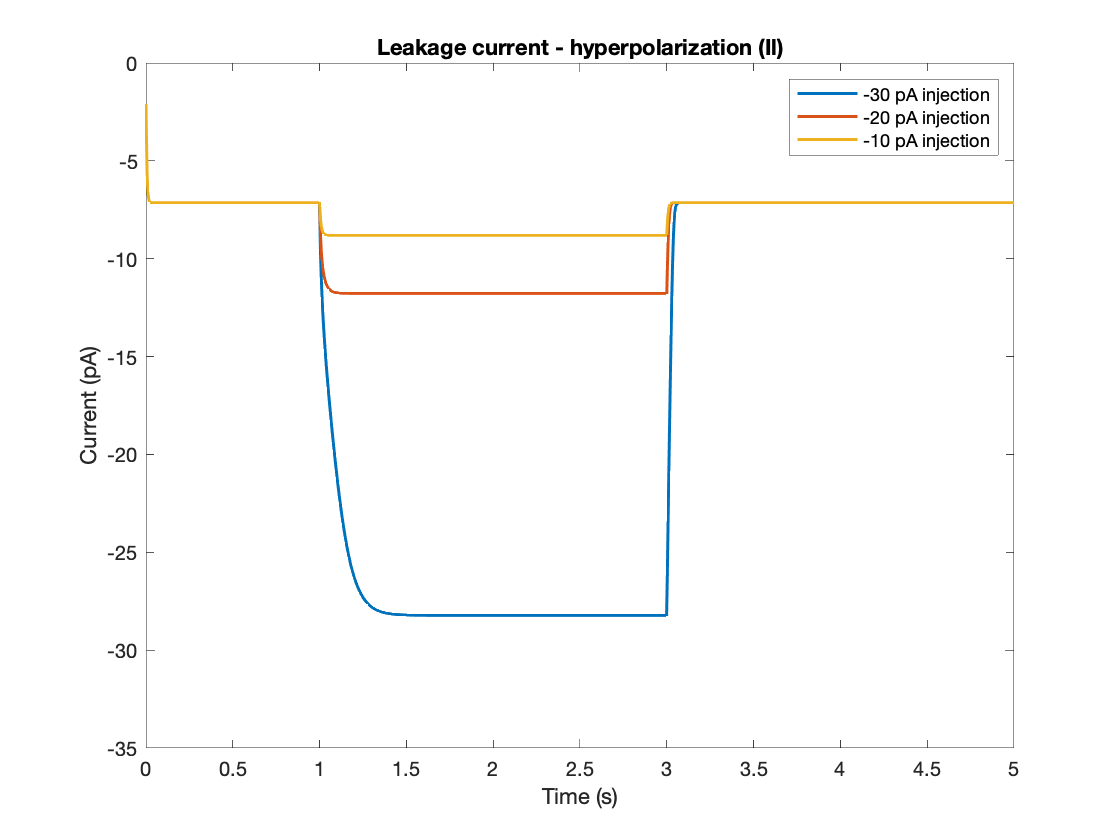

% Compute currents.
Il_30 = calcIl(newV_30);
Il_20 = calcIl(newV_20);
Il_10 = calcIl(newV_10);

% Plot the results.
plot(new_T, Il_30, new_T, Il_20, new_T, Il_10, 'LineWidth', 1.5)
ylim([-35 0])
title('Leakage current - hyperpolarization (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')
legend('-30 pA injection','-20 pA injection','-10 pA injection')

*Leakage current (depolarization)*

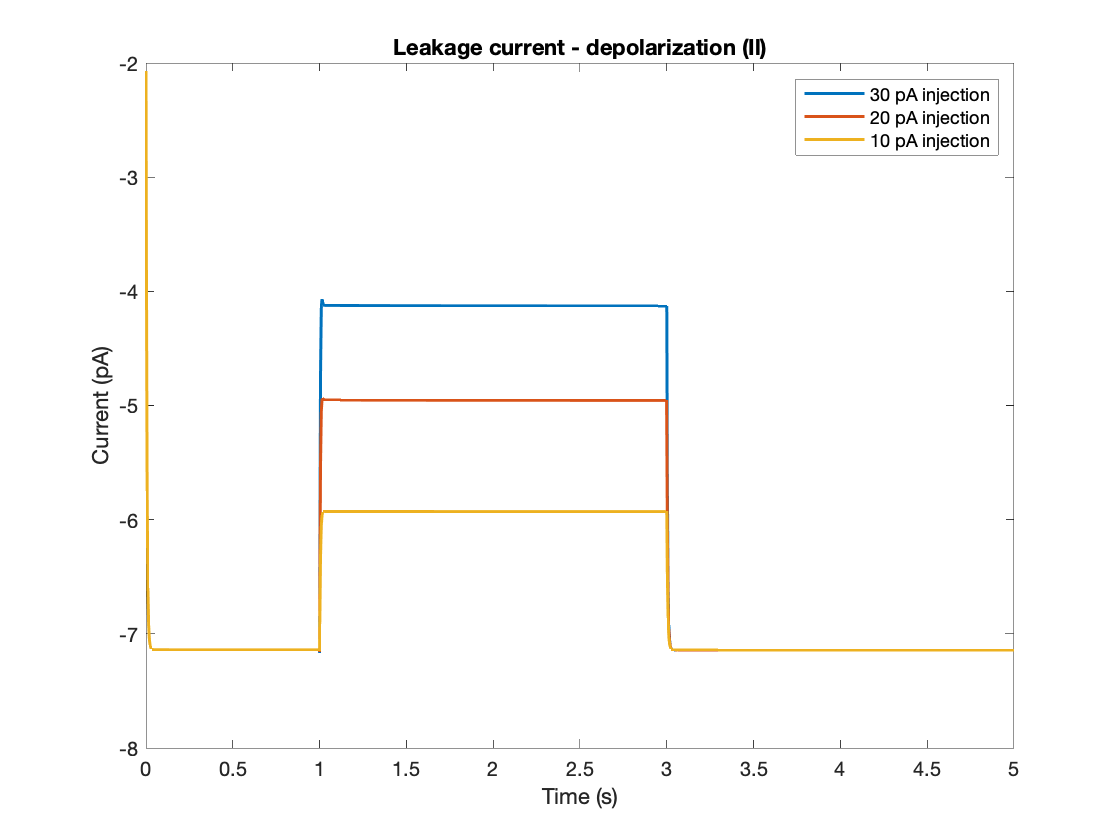

% Compute currents.
Il30 = calcIl(newV30);
Il20 = calcIl(newV20);
Il10 = calcIl(newV10);

% Plot the results.
plot(newT, Il30, newT, Il20, newT, Il10, 'LineWidth', 1.5)
ylim([-8 -2])
title('Leakage current - depolarization (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')
legend('30 pA injection','20 pA injection','10 pA injection')